## time

n = (length(kinematic.time())/10);
t = 0:0.1:n-0.1;

EKF Data 

%% ekf 
x_ekf = kinematic.state(1,:);
y_ekf = kinematic.state(2,:);
z_ekf = kinematic.state(3,:);

dx_ekf = kinematic.state(4,:);
dy_ekf = kinematic.state(5,:);
dz_ekf = kinematic.state(6,:);

ddx_ekf = kinematic.state(7,:);
ddy_ekf = kinematic.state(8,:);
ddz_ekf = kinematic.state(9,:);

phi_ekf = kinematic.state(10,:);
theta_ekf = kinematic.state(11,:);
psi_ekf = kinematic.state(12,:);

dphi_ekf = kinematic.state(13,:);
dtheta_ekf = kinematic.state(14,:);
dpsi_ekf = kinematic.state(15,:);

ddphi_ekf = kinematic.state(16,:);
ddtheta_smooth = kinematic.state(17,:);
ddpsi_ekf = kinematic.state(18,:);

Smoother data 


%% ekf 
x_smooth = xSmooth(1,:);
y_smooth = xSmooth(2,:);
z_smooth = xSmooth(3,:);

dx_smooth = xSmooth(4,:);
dy_smooth = xSmooth(5,:);
dz_smooth = xSmooth(6,:);

ddx_smooth = xSmooth(7,:);
ddy_smooth = xSmooth(8,:);
ddz_smooth = xSmooth(9,:);

phi_smooth = xSmooth(10,:);
th_smooth = xSmooth(11,:);
psi_smooth = xSmooth(12,:);

dphi_smooth = xSmooth(13,:);
dth_smooth = xSmooth(14,:);
dpsi_smooth = xSmooth(15,:);

ddphi_smooth = xSmooth(16,:);
ddth_smooth = xSmooth(17,:);
ddpsi_smooth = xSmooth(18,:);


EKF PLOTS

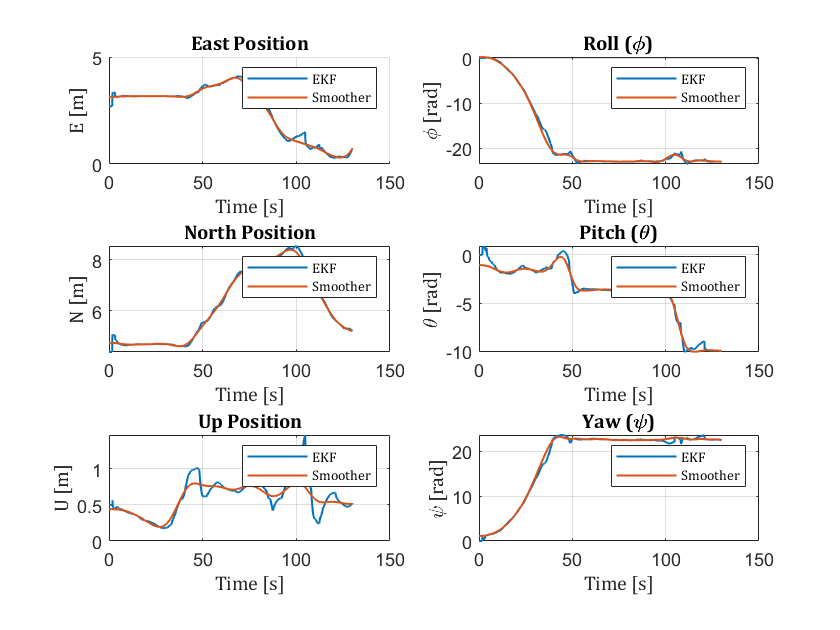

%% plot EKF 
figure()
subplot(3,2,1)
hold on
plot(t,x_ekf, 'LineWidth',1)
hold on
plot(t,x_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'E [m]'},'FontSize',8,'FontName','Cambria');
title({'East Position'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,3)
plot(t,y_ekf, 'LineWidth',1)
hold on
plot(t,y_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'N [m]'},'FontSize',8,'FontName','Cambria');
title({'North Position'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,5)
plot(t,z_ekf, 'LineWidth',1)
hold on
plot(t,z_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'U [m]'},'FontSize',8,'FontName','Cambria');
title({'Up Position'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,2)
plot(t,phi_ekf, 'LineWidth',1)
hold on
plot(t,phi_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'\phi [rad]'},'FontSize',8,'FontName','Cambria');
title({'Roll (\phi)'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,4)
plot(t,theta_ekf, 'LineWidth',1)
hold on
plot(t,th_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'\theta [rad]'},'FontSize',8,'FontName','Cambria');
title({'Pitch (\theta)'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,6)
plot(t,psi_ekf, 'LineWidth',1)
hold on
plot(t,psi_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'\psi [rad]'},'FontSize',8,'FontName','Cambria');
title({'Yaw (\psi)'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

derivatives

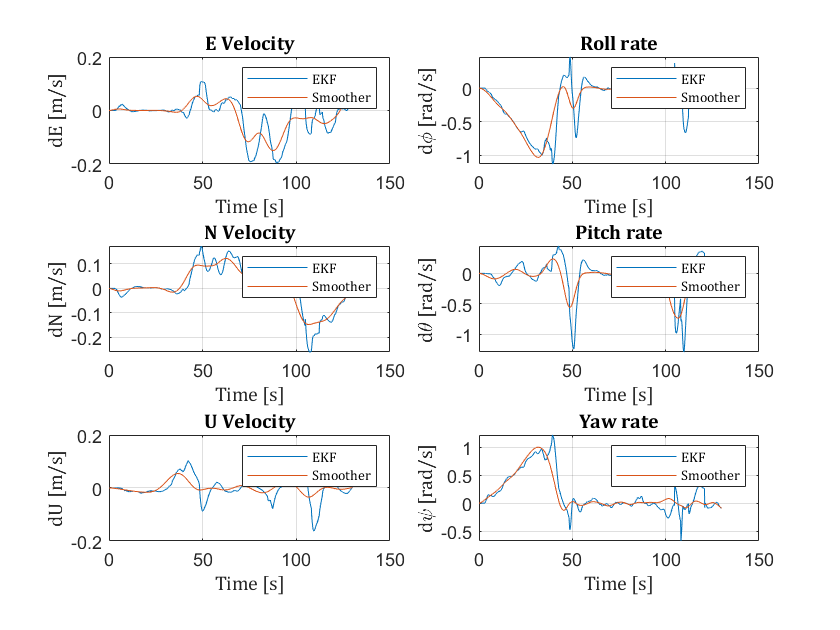

sz = 2;
figure()
subplot(3,2,1)
plot(t,dx_ekf)
hold on
plot(t,dx_smooth)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'dE [m/s]'},'FontSize',8,'FontName','Cambria');
title({'E Velocity'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,3)
plot(t,dy_ekf)
hold on
plot(t,dy_smooth)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'dN [m/s]'},'FontSize',8,'FontName','Cambria');
title({'N Velocity'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,5)
plot(t,dz_ekf)
hold on
plot(t,dz_smooth)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'dU [m/s]'},'FontSize',8,'FontName','Cambria');
title({'U Velocity'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,2)
plot(t,dphi_ekf)
hold on
plot(t,dphi_smooth)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'d\phi [rad/s]'},'FontSize',8,'FontName','Cambria');
title({'Roll rate'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,4)
plot(t,dtheta_ekf)
hold on
plot(t,dth_smooth)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'d\theta [rad/s]'},'FontSize',8,'FontName','Cambria');
title({'Pitch rate'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,6)
plot(t,dpsi_ekf)
hold on
plot(t,dpsi_smooth)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'d\psi [rad/s]'},'FontSize',8,'FontName','Cambria');
title({'Yaw rate'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')

3d trajectory

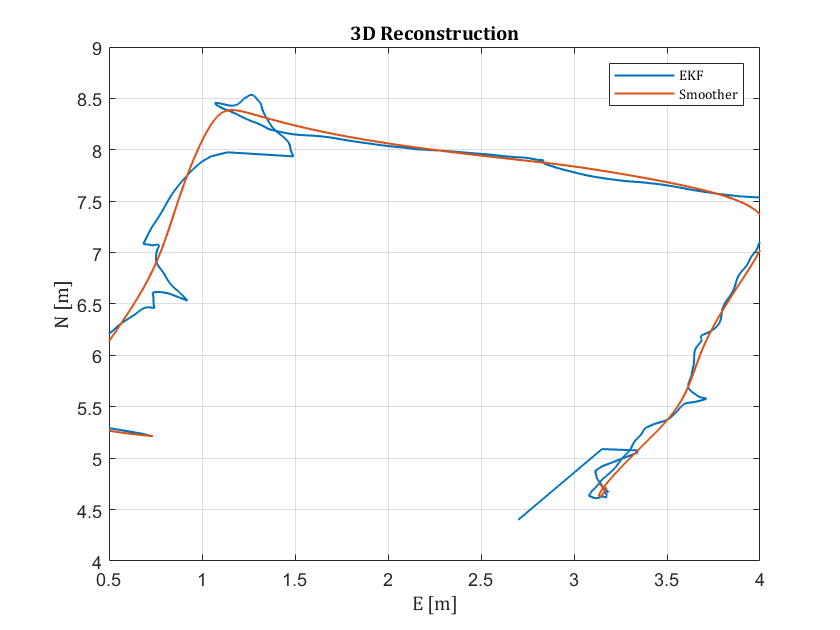

figure()
plot(x_ekf, y_ekf, 'LineWidth',1)
hold on
plot(x_smooth, y_smooth, 'LineWidth',1)
xlabel({'E [m]'},'FontSize',8,'FontName','Cambria');
ylabel({'N [m]'},'FontSize',8,'FontName','Cambria');
title({'3D Reconstruction'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'EKF','Smoother'},'FontSize',7,'FontName','Cambria')
xlim([0.5,4])

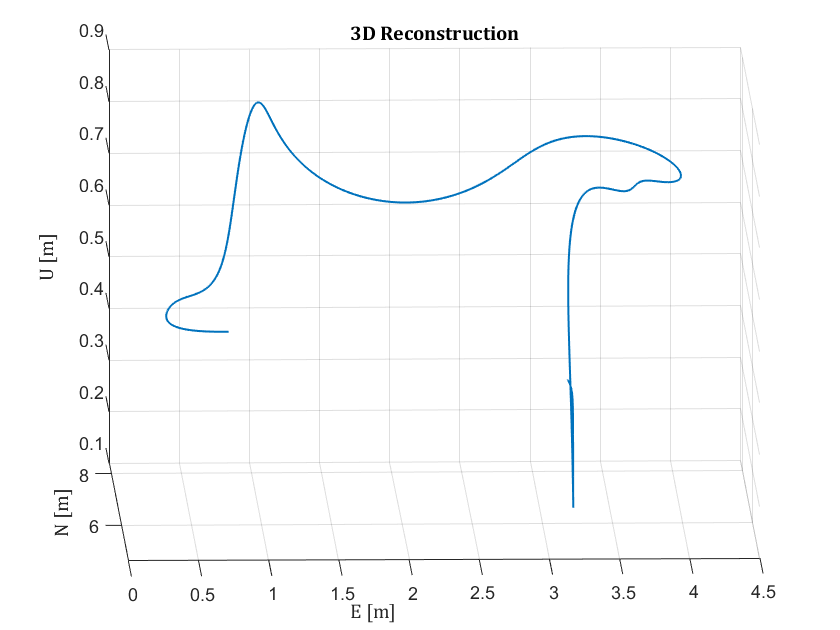


figure()
plot3(x_smooth, y_smooth,z_smooth, 'LineWidth',1)
xlabel({'E [m]'},'FontSize',8,'FontName','Cambria');
ylabel({'N [m]'},'FontSize',8,'FontName','Cambria');
zlabel({'U [m]'},'FontSize',8,'FontName','Cambria');
title({'3D Reconstruction'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 

standrad

x_std = std(x_ekf)

x_std = 1.2101

y_std = std(y_ekf)

y_std = 1.3867

z_std = std(z_ekf)

z_std = 0.2433


x_std_sm = std(x_smooth)

x_std_sm = 1.2153

y_std_sm = std(y_smooth)

y_std_sm = 1.3700

z_std_sm = std(z_smooth)

z_std_sm = 0.1816